# **Fermentation of Lactose to lactic acid**

- 
$$\frac{\mathrm{dX}}{\mathrm{dt}}\;\;=\;\;\mu_{\mathrm{max}} \ldotp X\ldotp \left(1\;\;-\;\;\frac{P\;\;-\;\;P_{\mathrm{ix}} }{P_{\mathrm{mx}} \;\;-\;\;P_{\mathrm{ix}} }\right)$$


- 
$$\frac{\textrm{d}P}{\textrm{dt}}\;\;=\;\alpha \ldotp \frac{\mathrm{dX}}{\mathrm{dt}}\;\;\;+\;\;\;q_{\mathrm{pmax}} \;\ldotp X\ldotp \left(\;\;\frac{S\;\;}{K_{\mathrm{sp}} \;+S}\right)$$


- 
$$\frac{\mathrm{dS}}{\textrm{dt}}\;\;=\;-1\ldotp \;\;q_{s\max } \;\ldotp X\ldotp \left(\;\;\frac{K_{\mathrm{is}} \;\;}{K_{\mathrm{is}} \;+S}\right)$$


where:

- X - cell biomass concentration

- P - product lactate concentration

- S - substrate lactose concentration

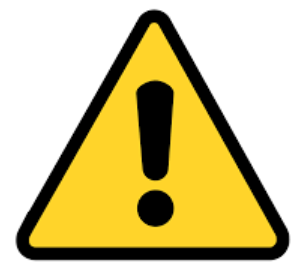

**FLAG and DISCUSS:**

- How should we handle the potential "divide by ZERO" events in the *dP/dt* and *dS/dt* equations. 

## Read in our system parameters from our Data dictionary:

ode_params_table = readtable('bh_our_params_dictionary.xlsx', 'Sheet', 'ODE_params', 'ReadRownames', true)

ode_params_table = 11×3 table
                   Value      Units            Description       
                  ________    ______    _________________________

    K_is               100    'g/L'     ''                       
    K_sp               205    'g/L'     'initial stable time'    
    P_ix              2.39    'TBC'     'end ph'                 
    P_mx              25.9    'TBC'     'end ph'                 
    alpha               15    'TBC'     'decrease rate'          
    mu_max           0.909    '1/hr'    ''                       
    q_pmax            0.05    'TBC'     'decrease rate sig'      
    q_smax          180.42    'TBC'     ''                       
    in_lactate           0    'g/L'     'initial lacta

And create a struct that we'll use inside the Simulink model:

params_ode.mu_max = ode_params_table{'mu_max',  'Value'};
params_ode.P_ix   = ode_params_table{'P_ix',    'Value'};
params_ode.P_mx   = ode_params_table{'P_mx',    'Value'};
params_ode.alpha  = ode_params_table{'alpha',   'Value'};
params_ode.q_pmax = ode_params_table{'q_pmax',  'Value'};
params_ode.K_sp   = ode_params_table{'K_sp',    'Value'};
params_ode.q_smax = ode_params_table{'q_smax',  'Value'};
params_ode.K_is   = ode_params_table{'K_is',    'Value'};

params_ode.X_0    = ode_params_table{'in_cell',   'Value'};
params_ode.P_0    = ode_params_table{'in_lactate','Value'};
params_ode.S_0    = ode_params_table{'in_lactose','Value'};

## Open our Simulink model:

We're going to implement the 3 odes in Simulink ... and we're going to demonstrate 2 different techniques/methods for modelling the system:

- Method_#1: we'll use "only" Simulink blocks, and we'll represent each of the 3 ODEs as separate SUBSYSTEMS.

- Method_#2: we'll still use Simulink blocks, but we'll ALSO use a "MATLAB Function Block" ... which we'll use to define the 3 ODEs.

% THE_MODEL = 'bh_lactose_model';
% open_system(THE_MODEL);